# การวิเคราะห์เชิงความถี่

# ตอนที่ 6 : การกรองสัญญาณพื้นฐาน และแผนภาพโบเด (ฺBasic Filtering & Bode plot)

กระบวนการกรองสัญญาณ (filtering) คือการลดทอนสัญญาณที่อยู่ในย่านความถี่ (band) ที่ไม่ต้องการให้น้อยลง 

Pass Band : ย่านความถี่ของสัญญาณที่ตัวกรอง (filter) ให้ผ่าน

Stop Band : ย่านความถี่ของสัญญาณที่ตัวกรองไม่ให้ผ่าน

Cutoff Frequency : ความถี่ ณ ขอบเขตระหว่างการให้สัญญาณผ่านและไม่ผ่าน

เราจะเริ่มศึกษาพื้นฐานของกระบวนการกรองสัญญาณจากตัวกรองแบบอนาล็อกอันดับที่หนึ่ง (first-order analog filter)

กำหนดให้วงจร RC อันดับที่หนึ่ง (first-order RC circuit) เป็นดังต่อไปนี้

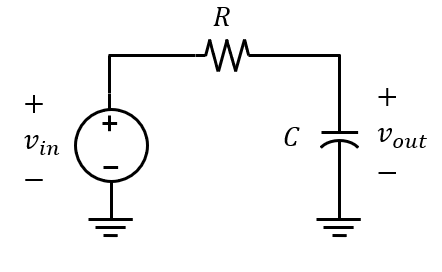

โดยที่ 

$R$ คือความต้านทาน (resistance) ของตัวต้านทาน

$C$ คือความจุ (capacitance) ของตัวเก็บประจุ

$v_{\textrm{in}}$ คือแรงดันไฟฟ้าอินพุต (input voltage)

$v_{\textrm{out}}$คือแรงดันไฟฟ้าเอ้าท์พุต (output voltage)

เราสามารถใช้กฎของ Kirchoff ในการหาแบบจำลองทางคณิตศาสตร์ดังต่อไปนี้


$$\begin{array}{l}
v_{\mathrm{in}} =Ri+v_c \\
i=C\frac{{dv}_c }{dt}\\
v_{\mathrm{out}} =v_c 
\end{array}$$


หรือ


$$v_{\mathrm{in}} =RC\frac{{dv}_{\mathrm{out}} }{dt}+v_{\mathrm{out}}$$


**เราสามารถวิเคราะห์ระบบโดยใช้โดเมนของลาปลาซเพื่อหาฟังก์ชันถ่ายโอน (transfer function)** ซึ่งสามารถเขียนได้ดังต่อไปนี้


$$\begin{array}{l}
\mathit{\mathbf{L}}\left\lbrace v_{\mathrm{in}} \right\rbrace =\mathit{\mathbf{L}}\left\lbrace RC\frac{{dv}_{\mathrm{out}} }{dt}+v_{\mathrm{out}} \right\rbrace \\
V_{\mathrm{in}} \left(s\right)=RCsV_{\mathrm{out}} \left(s\right)+V_{\mathrm{out}} \left(s\right)\\
G\left(s\right)=\frac{V_{\mathrm{out}} \left(s\right)}{V_{\mathrm{in}} \left(s\right)}\;=\frac{1}{RCs+1}=\frac{\frac{1}{RC}}{s+\frac{1}{RC}}=\frac{\omega_c }{s+\omega_c }
\end{array}$$


โดยที่ $G\left(s\right)$ คือฟังก์ชันถ่ายโอนของวงจร และ $\omega_c =\frac{1}{RC}$

**เราจะกำหนดให้อินพุตอยู่ในรูปของฟังก์ชันคลื่นไซน์ที่มีแอมพลิจูดเท่ากับ **$R_{\textrm{in}}$** และมุมเฟส **$\phi_{\textrm{in}}$ ซึ่งเขียนได้ดังต่อไปนี้ 


$$\begin{array}{l}
v_{\mathrm{in}} \left(t\right)=R_{\mathrm{in}} \cos \left(\omega t+\phi_{\mathrm{in}} \right):\;\cos \left(A\pm B\right)=\mathrm{cosAcosB}\;\mp \mathrm{sinAsinB}\\
v_{\mathrm{in}} \left(t\right)=R_{\mathrm{in}} \cos \left(\phi_{\mathrm{in}} \right)\cos \left(\omega t\right)-R_{\mathrm{in}} \sin \left(\phi_{\mathrm{in}} \right)\sin \left(\omega t\right)\\
V_{\mathrm{in}} \left(s\right)=R_{\mathrm{in}} \left(\frac{\cos \left(\phi_{\mathrm{in}} \right)s-\sin \left(\phi_{\mathrm{in}} \right)\omega }{s^2 +\omega^2 }\right)
\end{array}$$


จากนั้น เราสามารถหาผลเฉลยของสมการเชิงอนุพันธ์โดยแก้สมการในโดเมนของลาปลาซ ซึ่งมีขั้นตอนดังต่อไปนี้

เราสามารถนำอินพุตไปคูณกับฟังก์ชันถ่ายโอนและแยกพจน์ให้อยู่ในรูปผลบวกโดยใช้เทคนิค partial fraction


$$\begin{array}{l}
\mathrm{จาก}\;\frac{V_{\mathrm{out}} \left(s\right)}{V_{\mathrm{in}} \left(s\right)}=\frac{\omega_c }{s+\omega_c }\;\;\mathbf{และ}\;\;V_{\mathrm{in}} \left(s\right)=R_{\mathrm{in}} \left(\frac{\cos \left(\phi_{\mathrm{in}} \right)s-\sin \left(\phi_{\mathrm{in}} \right)\omega }{s^2 +\omega^2 }\right)\\
V_{\mathrm{out}} \left(s\right)=\left(\frac{\omega_c }{s+\omega_c }\right)R_{\mathrm{in}} \left(\frac{\cos \left(\phi_{\mathrm{in}} \right)s-\sin \left(\phi_{\mathrm{in}} \right)\omega }{s^2 +\omega^2 }\right)\\
V_{\mathrm{out}} \left(s\right)=\frac{K_1 }{s+\omega_c }+\frac{K_2 s+K_3 }{s^2 +\omega^2 }=\frac{K_1 \left(s^2 +\omega^2 \right)+\left(K_2 s+K_3 \right)\left(s+\omega_c \right)}{\left(s+\omega_c \right)\left(s^2 +\omega^2 \right)}
\end{array}$$


เราสามารถจับสัมประสิทธิ์เพื่อที่จะได้ระบบสมการเชิงเส้นดังต่อไปนี้


$$\begin{array}{l}
K_1 +K_2 =0\\
K_3 +\omega_c K_2 =\omega_c R_{\mathrm{in}} \cos \left(\phi_{\mathrm{in}} \right)\\
\omega^2 K_1 +\omega_c K_3 =-\omega_c \omega R_{\mathrm{in}} \sin \left(\phi_{\mathrm{in}} \right)
\end{array}$$


เราจะได้ว่าสัมประสิทธิ์แต่ละตัวจะมีความสัมพันธ์ดังต่อไปนี้

$\begin{array}{l}
K_1 =-\frac{R_{\textrm{in}} \omega_c }{\omega^2 +\omega_c^2 }\left\lbrack \omega \sin \left(\phi_{\textrm{in}} \right)+\omega_c \cos \left(\phi_{\textrm{in}} \right)\right\rbrack \\
K_2 =\frac{R_{\textrm{in}} \omega_c }{\omega^2 +\omega_c^2 }\left\lbrack \omega \sin \left(\phi_{\textrm{in}} \right)+\omega_c \cos \left(\phi_{\textrm{in}} \right)\right\rbrack \\
K_3 =\frac{R_{\textrm{in}} \omega_c \omega }{\omega^2 +\omega_c^2 }\left\lbrack \omega \cos \left(\phi_{\textrm{in}} \right)-\omega_c \sin \left(\phi_{\textrm{in}} \right)\right\rbrack 
\end{array}$0.

เมื่อเราแทนค่า $K_1$ , $K_2$ , และ $K_3$ ในผลรวม เราจะสามารถเขียน $V_{\textrm{out}} \left(s\right)$ในรูปต่อไปนี้


$$V_{\textrm{out}} \left(s\right)=-\frac{R_{\textrm{in}} \omega_c }{\omega^2 +\omega_c^2 }\left\lbrack \omega \sin \left(\phi_{\textrm{in}} \right)+\omega_c \cos \left(\phi_{\textrm{in}} \right)\right\rbrack \left(\frac{1}{s+\omega_c }\right)+\frac{R_{\textrm{in}} \omega_c }{\omega^2 +\omega_c^2 }\left(\frac{\left\lbrack \omega \sin \left(\phi_{\textrm{in}} \right)+\omega_c \cos \left(\phi_{\textrm{in}} \right)\right\rbrack s+\left\lbrack \omega \cos \left(\phi_{\textrm{in}} \right)-\omega_c \sin \left(\phi_{\textrm{in}} \right)\right\rbrack \omega }{s^2 +\omega^2 }\right)$$


หากเราใช้หลักการหาลาปลาซผกผันดังต่อไปนี้


$${\mathit{\mathbf{L}}}^{-1} \left(\frac{\textrm{as}+b\omega }{s^2 +\omega^2 }\right)=\sqrt{a^2 +b^2 }\cos \left(\omega t+\tan^{-1} \left(\frac{-b}{a}\right)\right)$$


**เราสามารถหาเอ้าท์พุตในรูปของผลรวมของผลตอบสนองแบบชั่วครู่และผลตอบสนองแบบคงตัว**ในโดเมนของเวลาได้ดังต่อไปนี้


$$v_{\mathrm{out}} \left(t\right)=v_t \left(t\right)+v_s \left(t\right)$$



$$\begin{array}{l}
v_t \left(t\right)=-\frac{R_{\mathrm{in}} \omega_c }{\omega^2 +\omega_c^2 }\left\lbrack \omega \sin \left(\phi_{\mathrm{in}} \right)+\omega_c \cos \left(\phi_{\mathrm{in}} \right)\right\rbrack e^{-\omega_c t} \\
v_s \left(t\right)=R_{\mathrm{out}} \cos \left(\omega t+\phi_{\mathrm{out}} \right)\\
R_{\mathrm{out}} =\frac{R_{\mathrm{in}} \omega_c }{\omega^2 +\omega_c^2 }\sqrt{{\left\lbrack \omega \sin \left(\phi_{\mathrm{in}} \right)+\omega_c \cos \left(\phi_{\mathrm{in}} \right)\right\rbrack }^2 +{\left\lbrack \omega \cos \left(\phi_{\mathrm{in}} \right)-\omega_c \sin \left(\phi_{\mathrm{in}} \right)\right\rbrack }^2 }=\frac{R_{\mathrm{in}} \omega_c }{\omega^2 +\omega_c^2 }\sqrt{\omega^2 +\omega_c^2 }=\frac{1}{\sqrt{1+{\left(\frac{\omega }{\omega_c }\right)}^2 }}R_{\mathrm{in}} \\
\phi_{\mathrm{out}} =\tan^{-1} \left(\frac{\omega_c \sin \left(\phi_{\mathrm{in}} \right)-\omega \cos \left(\phi_{\mathrm{in}} \right)}{\omega \sin \left(\phi_{\mathrm{in}} \right)+\omega_c \cos \left(\phi_{\mathrm{in}} \right)}\right)=\tan^{-1} \left(\frac{\tan \left(\phi_{\mathrm{in}} \right)-\frac{\omega }{\omega_c }}{1+\frac{\omega }{\omega_c }\tan \left(\phi_{\mathrm{in}} \right)}\right)=\tan^{-1} \left(\tan \left(\phi_{\mathrm{in}} -\tan^{-1} \left(\frac{\omega }{\omega_c }\right)\right)\right)=\phi_{\mathrm{in}} -\tan^{-1} \left(\frac{\omega }{\omega_c }\right)
\end{array}$$


เมื่อเวลาผ่านไป ผลตอบสนองแบบชั่วครู่จะลู่เข้าสู่ศูนย์เนื่องจาก


$$\lim_{t\to \infty } \left\lbrace v_t \left(t\right)\right\rbrace =-\frac{R_{\mathrm{in}} \omega_c }{\omega^2 +\omega_c^2 }\left\lbrack \omega \sin \left(\phi_{\mathrm{in}} \right)+\omega_c \cos \left(\phi_{\mathrm{in}} \right)\right\rbrack \lim_{t\to \infty } \left\lbrace e^{-\omega_c t} \right\rbrace =0$$


**เราจึงวิเคราะห์ความสัมพันธ์ของความถี่กับผลตอบสนองแบบคงตัวเท่านั้น **


$$v_{\mathrm{out}} \left(t\right)=R_{\mathrm{out}} \cos \left(\omega t+\phi_{\mathrm{out}} \right)$$


หากเราวิเคราะห์ที่แอมพลิจูดของคลื่นเอ้าท์พุต เราจะได้ได้ความสัมพันธ์ในเชิงของความถี่เชิงมุมดังต่อไปนี้


$$R_{\textrm{out}} =\frac{1}{\sqrt{1+{\left(\frac{\omega }{\omega_c }\right)}^2 }}R_{\textrm{in}}$$


เ**พื่อการวิเคราะห์ความสามารถในการลอดทอนสัญญาณ เราสามารถหาอัตราส่วนขนาดในเดซิเบล**ได้ดังต่อไปนี้


$${\left|G\left(\omega \right)\right|}_{\mathrm{dB}} =20\;\log_{10} \left(\frac{1}{\sqrt{1+{\left(\frac{\omega }{\omega_c }\right)}^2 }}\right)=-10\;\log_{10} \left(1+{\left(\frac{\omega }{\omega_c }\right)}^2 \right)$$


เนื่องจากฟังก์ชันดังกล่าวขึ้นอยู่กับพารามิเตอร์ $\omega_c$ เราจึงไม่สามารถวาดกราฟขึ้นมาได้ เพื่อให้การวิเคราะห์นั้นไม่ขึ้นอยู่กับค่า $\omega_c$ **เราสามารถทำการวิเคราห์ความถี่ในรูปแบบความถี่สัมพัทธ์ (relative frequency) โดยกำหนดให้ความถี่สัมพัทธ์ของตัวอย่างเทียบกับ **$\omega_c$** เราจะได้ความถี่สัมพัทธ์**ดังต่อไปนี้


$$\omega^* =\frac{\omega }{\omega_c }$$


**ค่าของความถี่สัมพัทธ์คือความสัมพันธ์ที่เป็นอัตราส่วนระหว่างความถี่ และค่าที่เลือกที่จะเปรียบเทียบ** 

ข้อสังเกตของความถี่มีดังต่อไปนี้

- ความถี่ $\omega$ โดยทั่วไปอาจถูกมองว่าเป็นลบได้ 

- ความถี่สัมพัทธ์ $\omega^*$ จะเป็นบวกเสมอ

- เพื่อการวิเคราะห์ในย่านความถี่ที่กว้าง เสกลของความถี่ในกราฟมักจะเป็นเสกลล็อกการิทึม (log-scale) 

จากความถี่สัมพัทธ์ที่กำหนด เราจะสามารถเขียนอัตราส่วนขนาดที่ขึ้นอยู่กับความถี่สัมพัทธ์ได้ดังต่อไปนี้


$${\left|G\left(\omega^* \right)\right|}_{\mathrm{dB}} =-10\;\log_{10} \left(1+{\left(\omega^* \right)}^2 \right)$$


ซึ่งเราสามารถกราฟความสัมพันธ์ได้ดังต่อไปนี้

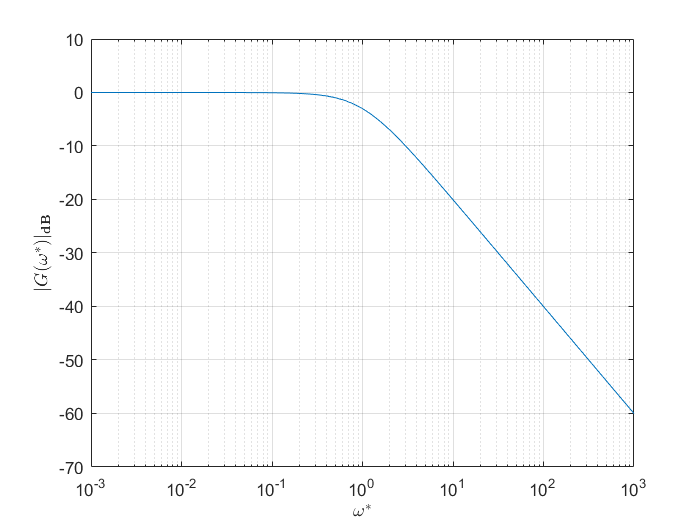

clf;
ax = axes;
w = 10.^(-3:0.1:3);
semilogx(ax,w,-10*log10(1+w.^2));
grid(ax,'on');
axis(ax,[min(w) max(w) -70 10]);
xlabel('$\omega^*$','Interpreter',"latex")
ylabel('$|G(\omega^*)|_\mathbf{dB}$','Interpreter',"latex")

ข้อสังเกตของกราฟมีดังต่อไปนี้

- เสกลที่ถูกใช้ในตัวแปร $\omega^*$**เป็นเสกลล็อกการิทึม** พื้นที่กราฟระหว่าง ${10}^k$ และ ${10}^{k+1}$ จะถูกแบ่งเป็น 10 ช่องย่อยๆ ซึ่งระยะห่างจะเป็นไปตามเสกลของล็อกการิทึม เส้นของตาราง (grid) ที่ถูกตีมีค่าตรงกับค่า  $a\cdot {10}^k$ โดยที่$a=\left\lbrace 1,2,\cdots ,9\right\rbrace$

- เสกลที่ถูกใช้ในแกนแนวตั้งเป็นเสกลเชิงเส้น แต่ตัวแปรในแนวตั้งมีค่าเป็นเดซิเบล หากเรามองในมุมมองของอัตราส่วนขนาด(ปกติ) เสกลนี้ถือว่าเป็นเสกลล็อกการิทึมเช่นกัน แต่ถ้าหากมองในมุมมองของอัตราส่วนขนาดในเดซิเบล เสกลนี้ถือว่าเป็นเสกลเชิงเส้น

เราจะสังเกตได้ว่าอัตราส่วนขนาดในเดซิเบลมีค่าใกล้เคียงกับ $0\;\textrm{dB}$ หรือ $1$ ในช่วงที่ $\omega^* <1$ หรือ $\omega <\omega_c$ **การที่อัตราส่วนขนาดมีค่าใกล้เคียงกับ **$1$** หมายความว่าแอมพลิจูดของคลื่นเอ้าท์พุตมีขนาดใกล้เคียงกับแอมพลิจูดของคลื่นอินพุต** ในทางกลับกัน **เราจะสังเกตได้ว่าในช่วงที่ **$\omega^* >1$** หรือ **$\omega >\omega_c$** อัตราส่วนขนาดมีค่าน้อยกว่า **$0\;\textrm{dB}$** ซึ่งหมายความว่าแอมพลิจูดของคลื่นเอ้าท์พุตจะยิ่งถูกลดทอน **นอกจากนี้ เราจะสังเกตได้ว่าอัตราส่วนขนาดในเดซิเบลมีค่าลดลงด้วยอัตรา 20 เดซิเบลต่อการขยายความถี่สิบเท่า หรือ $20\;\left\lbrack \frac{\textrm{dB}}{\textrm{decade}}\right\rbrack$ซึ่งหมายความว่าสัญญาณจะถูกลดทอนมากขึ้นเมื่อความถี่เพิ่มขึ้น เราสามารถสรุปได้ว่า **ระบบดังกล่าวเป็นตัวกรองแบบ low-pass ที่ทำการกรองให้สัญญาณที่มีความถี่ต่ำกว่า **$\omega_c$**ผ่าน** (มีแอมพลิจูดที่ใกล้เคียงกับอินพุต) **และกรองสัญญาณที่มีความถี่สูงกว่า **$\omega_c$** ออก** (แอมพลิจูดถูกลดทอนอย่างมาก)  เราจะเรียก $\omega_c$ ว่าเป็นความถี่ตัด (cutoff frequency) 

เพื่อความชัดเจนในการกำหนดย่านความถี่ที่ตัวกรองให้ผ่าน เราสามารถใช้นิยามของอัตราส่วนพลังของระบบในการกำหนด ซึ่งอัตราส่วนพลัง ${\left|G\left(\omega^* \right)\right|}^2$ สามารถเขียนได้ดังต่อไปนี้


$${\left|G\left(\omega^* \right)\right|}^2 =\frac{1}{1+{\left(\omega^* \right)}^2 }$$


ย**่านของสัญญาณที่ให้ผ่าน (pass-band) **$\omega_p$** จะถูกกำหนดให้เป็นย่านของสัญญาณที่ทำให้อัตราส่วนพลังระบบมีค่ามากกว่าครึ่งของอัตราส่วนพลัง ณ อินพุตคงที่ (หรือ **$\omega^* =0$**) ** หรือ


$$\omega_p \in \left\lbrace \omega :{\left|G\left(\omega \right)\right|}^2 >\frac{1}{2}{\left|G\left(0\right)\right|}^2 \right\rbrace$$


หากเรานำอัตราส่วนพลังของตัวอย่างมาคำนวณหาย่านของสัญญาณที่ให้ผ่าน เราจะได้ความสัมพันธ์ดังต่อไปนี้


$$\begin{array}{l}
\frac{1}{1+{\left(\omega^* \right)}^2 }>\frac{1}{2}\cdot \frac{1}{1+{\left(0\right)}^2 }\\
{\left(\omega^* \right)}^2 >1\\
-1<\omega^* <1
\end{array}$$


นั่นเลยเป็นที่มาของการกำหนดความถี่ตัดที่ $\omega^* =1$เรากำหนดนิยามของความถี่ตัดอย่างเป็นทางการได้ดังต่อไปนี้

**ความถี่ตัด (cutoff frequency) คือขอบเขตของความถี่ที่เกิดการเปลี่ยนแปลงระหว่างการขยายกัยการลดทอน อัตราส่วนพลัง ณ ความถี่ตัดจะมีค่าเท่ากับ **$\frac{1}{2}$

 หากเราวิเคราะห์ที่มุมเฟสของคลื่นเอ้าท์พุต เราจะได้ความสัมพันธ์ในเชิงของความถี่เชิงมุมดังต่อไปนี้


$$\phi_{\textrm{out}} =\phi_{\textrm{in}} -\tan^{-1} \left(\frac{\omega }{\omega_c }\right)$$


เพื่อการวิเคราะห์การล่าช้าของสัญญาณ เราสามารถหาเฟสการเลื่อนได้ดังต่อไปนี้


$$\angle \left(G\left(\omega^* \right)\right)=-\tan^{-1} \left(\omega^* \right)$$


ซึ่งเราสามารถกราฟความสัมพันธ์ได้ดังต่อไปนี้

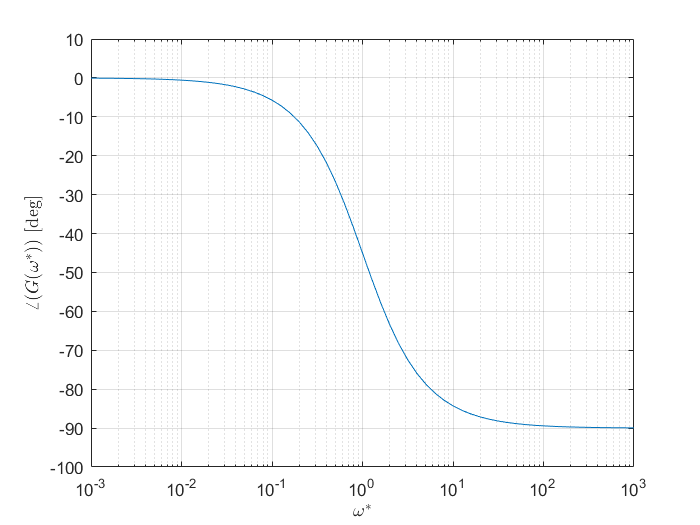

clf
ax = axes;
w = 10.^(-3:0.1:3);
semilogx(ax,w,-atan(w)*180/pi);
grid(ax,'on');
axis(ax,[min(w) max(w) -100 10]);
xlabel('$\omega^*$','Interpreter',"latex")
ylabel('$\angle(G(\omega^*))$ [deg]','Interpreter',"latex")

**เราจะสังเกตได้ว่าเฟสการเลื่อนของระบบจะมีมากขึ้นเพื่อความถี่เพิ่มขึ้น และเฟสการเลื่อนมีค่ามากที่สุดที่ -90 องศา**

เฟสการเลื่อนของระบบมีบทบาทต่อเสถียรภาพของระบบซึ่งเราจะศึกษาต่อในวิชาวิศวกรรมระบบควบคุม

**การกราฟความสัมพันธ์ระหว่างอัตราส่วนขนาด(magnitude)และเฟสการเลื่อนเมื่อเทียบกับความถี่ในเสกลที่กล่าวไป ถูกเรียกว่า แผนภาพโบเด/โบด (Bode plot) ซึ่งเป็นแผนภาพมาตรฐานในการวิเคราะห์เชิงความถี่**